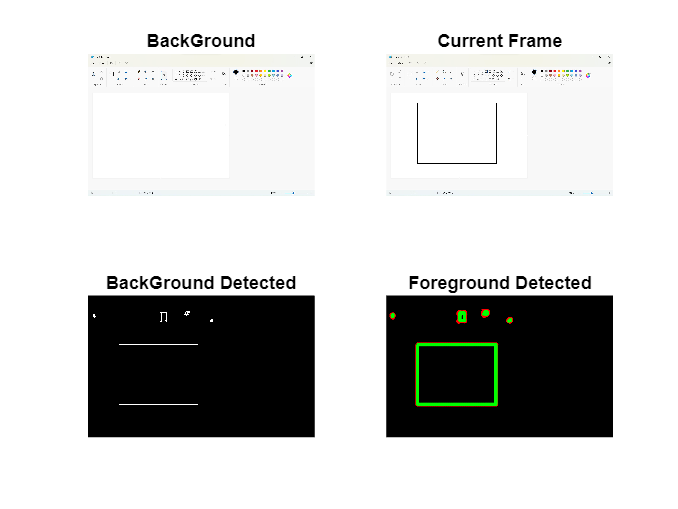

clc;
close all;
clear;
Background=imread('background.jpg');
%Read Current Frame
CurrentFrame=imread('original.jpg');
%Display Background and Foreground
subplot(2,2,1);imshow(Background);title('BackGround');
subplot(2,2,2);imshow(CurrentFrame);title('Current Frame');
%Convert RGB 2 HSV Color conversion
[Background_hsv]=round(rgb2hsv(Background));
[CurrentFrame_hsv]=round(rgb2hsv(CurrentFrame));
Out = bitxor(Background_hsv,CurrentFrame_hsv);
%Convert RGB 2 GRAY
Out=rgb2gray(Out);
%Read Rows and Columns of the Image
[rows column]=size(Out);
%Convert to Binary Image
for i=1:rows
for j=1:column

if Out(i,j) >0

BinaryImage(i,j)=1;

else

BinaryImage(i,j)=0;

end

end
end
%Apply Median filter to remove Noise
FilteredImage=medfilt2(BinaryImage,[5 5]);
%Boundary Label the Filtered Image
[L num1]=bwlabel(FilteredImage);

STATS=regionprops(L,'all');
cc=[];
removed=0;
%Remove the noisy regions
for i=1:num1
dd=STATS(i).Area;

if (dd < 500)

L(L==i)=0;
removed = removed + 1;
num1=num1-1;

else

end

end

[L2 num2]=bwlabel(L);
% Trace region boundaries in a binary image.

[B,L,N,A] = bwboundaries(L2);
%Display results

subplot(2,2,3),  imshow(L2);title('BackGround Detected');
subplot(2,2,4),  imshow(L2);title('Foreground Detected');

hold on;
for k=1:length(B),

if(~sum(A(k,:)))
boundary = B{k};
plot(boundary(:,2), boundary(:,1), 'r','LineWidth',2);

for l=find(A(:,k))'
boundary = B{l};
plot(boundary(:,2), boundary(:,1), 'g','LineWidth',2);
end

end

end